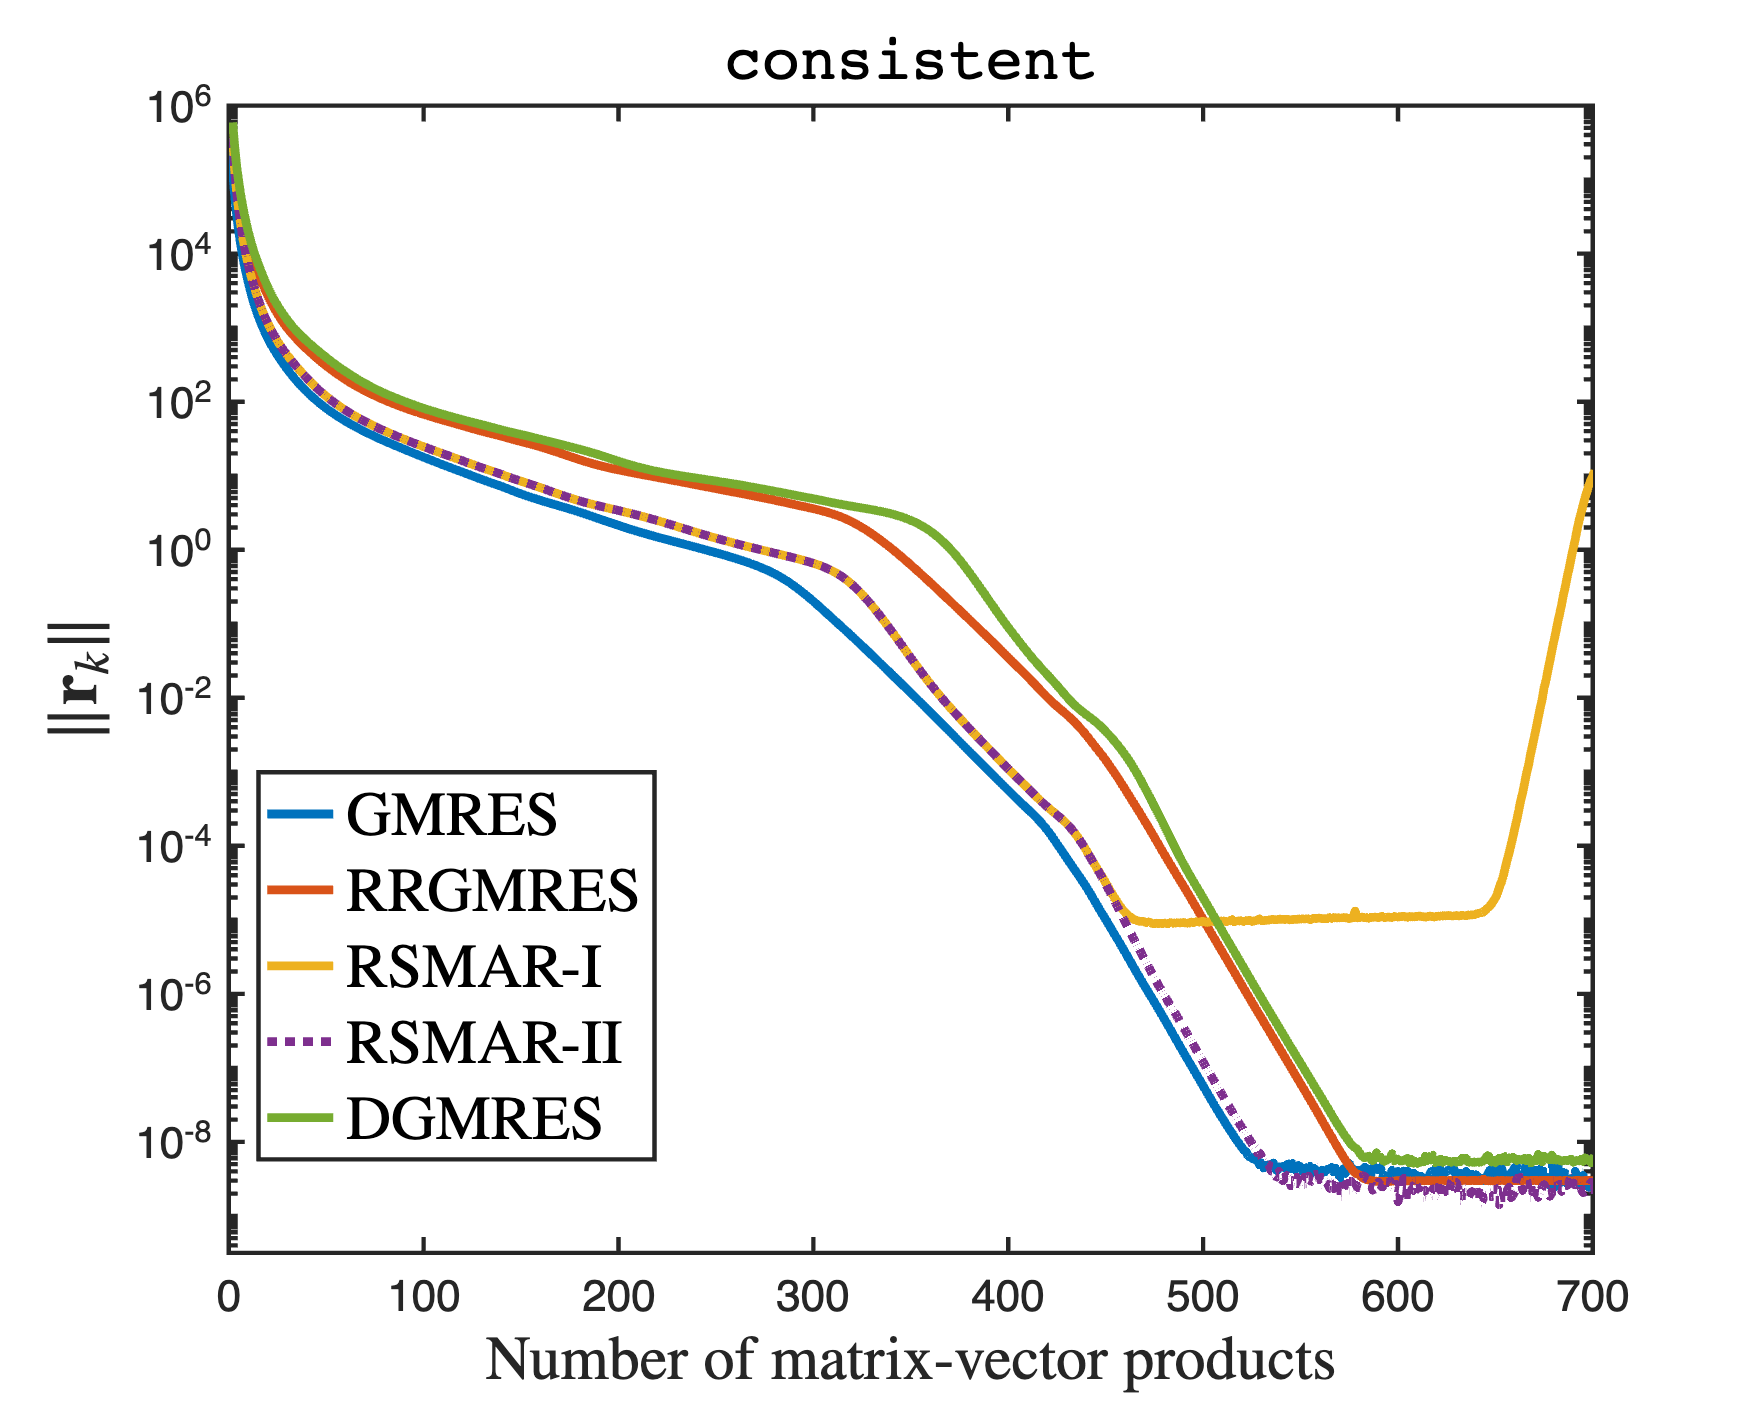

% Kui Du, Jia-Jun Fan, and Fang Wang 2024.01.21
clc; close all; clearvars;
% range symmetric singular consistent system
m = 100; h = 1 / m; d = 10;
a1 = 1 + d * h / 2;
a2 = 1 - d * h / 2;
one = ones(m, 1);
T = spdiags([a2*one, -4*one, a1*one], [-1, 0, 1], m, m);
T(m, 1) = a1; T(1, m) = a2;
A = spdiags([one, one], [-1, 1], m, m);
A(1, m) = 1; A(m, 1) = 1;
A = kron(A, speye(m)) + kron(speye(m), T);
A = A / h^2;
% s = svd(full(A)) cond(A)~2027

rng("default"); b = A*rand(m*m,1);
tol = 1e-9; maxit = 700;

[~, ~, gmres_resvec, ~] = gmres(A, b, tol, maxit, criteria=1);
[~, ~, rrgmres_resvec, ~] = rrgmres(A, b, tol, maxit, version=2, criteria=1);
[~, ~, rsmar1_resvec, ~] = rsmar(A, b, tol, maxit, version=1, criteria=1);
[~, ~, rsmar2_resvec, ~] = rsmar(A, b, tol, maxit, version=2, criteria=1);
[~, ~, dgmres_resvec, ~] = dgmres(A, b, tol, maxit, criteria=1);

set(0, 'defaultaxeslinewidth',  2);
set(0, 'defaultaxesfontsize',   20);
figure('Position',[180 120 800 640]);
semilogy(1:length(gmres_resvec), gmres_resvec, LineWidth=4);
hold on;
semilogy(2:length(rrgmres_resvec)+1, rrgmres_resvec, LineWidth=4);
semilogy(2:length(rsmar1_resvec)+1, rsmar1_resvec, LineWidth=4);
semilogy(2:length(rsmar2_resvec)+1, rsmar2_resvec, LineWidth=4, LineStyle=":");
semilogy(2:length(dgmres_resvec)+1, dgmres_resvec, LineWidth=4);
hold off;
xlim([0, maxit]), ylim([tol*10^(-0.5) 10^6])
title('{\tt consistent}', Interpreter='latex',FontSize=28);
xlabel('Number of matrix-vector products', Interpreter='latex', FontSize=28);
ylabel('$\|\mathbf{r}_k\|$', Interpreter='latex', FontSize=32);
legend({'GMRES', 'RRGMRES', 'RSMAR-I', 'RSMAR-II', 'DGMRES'}, Interpreter='latex', FontSize=28, Location='best');
print('bvp_con','-depsc')

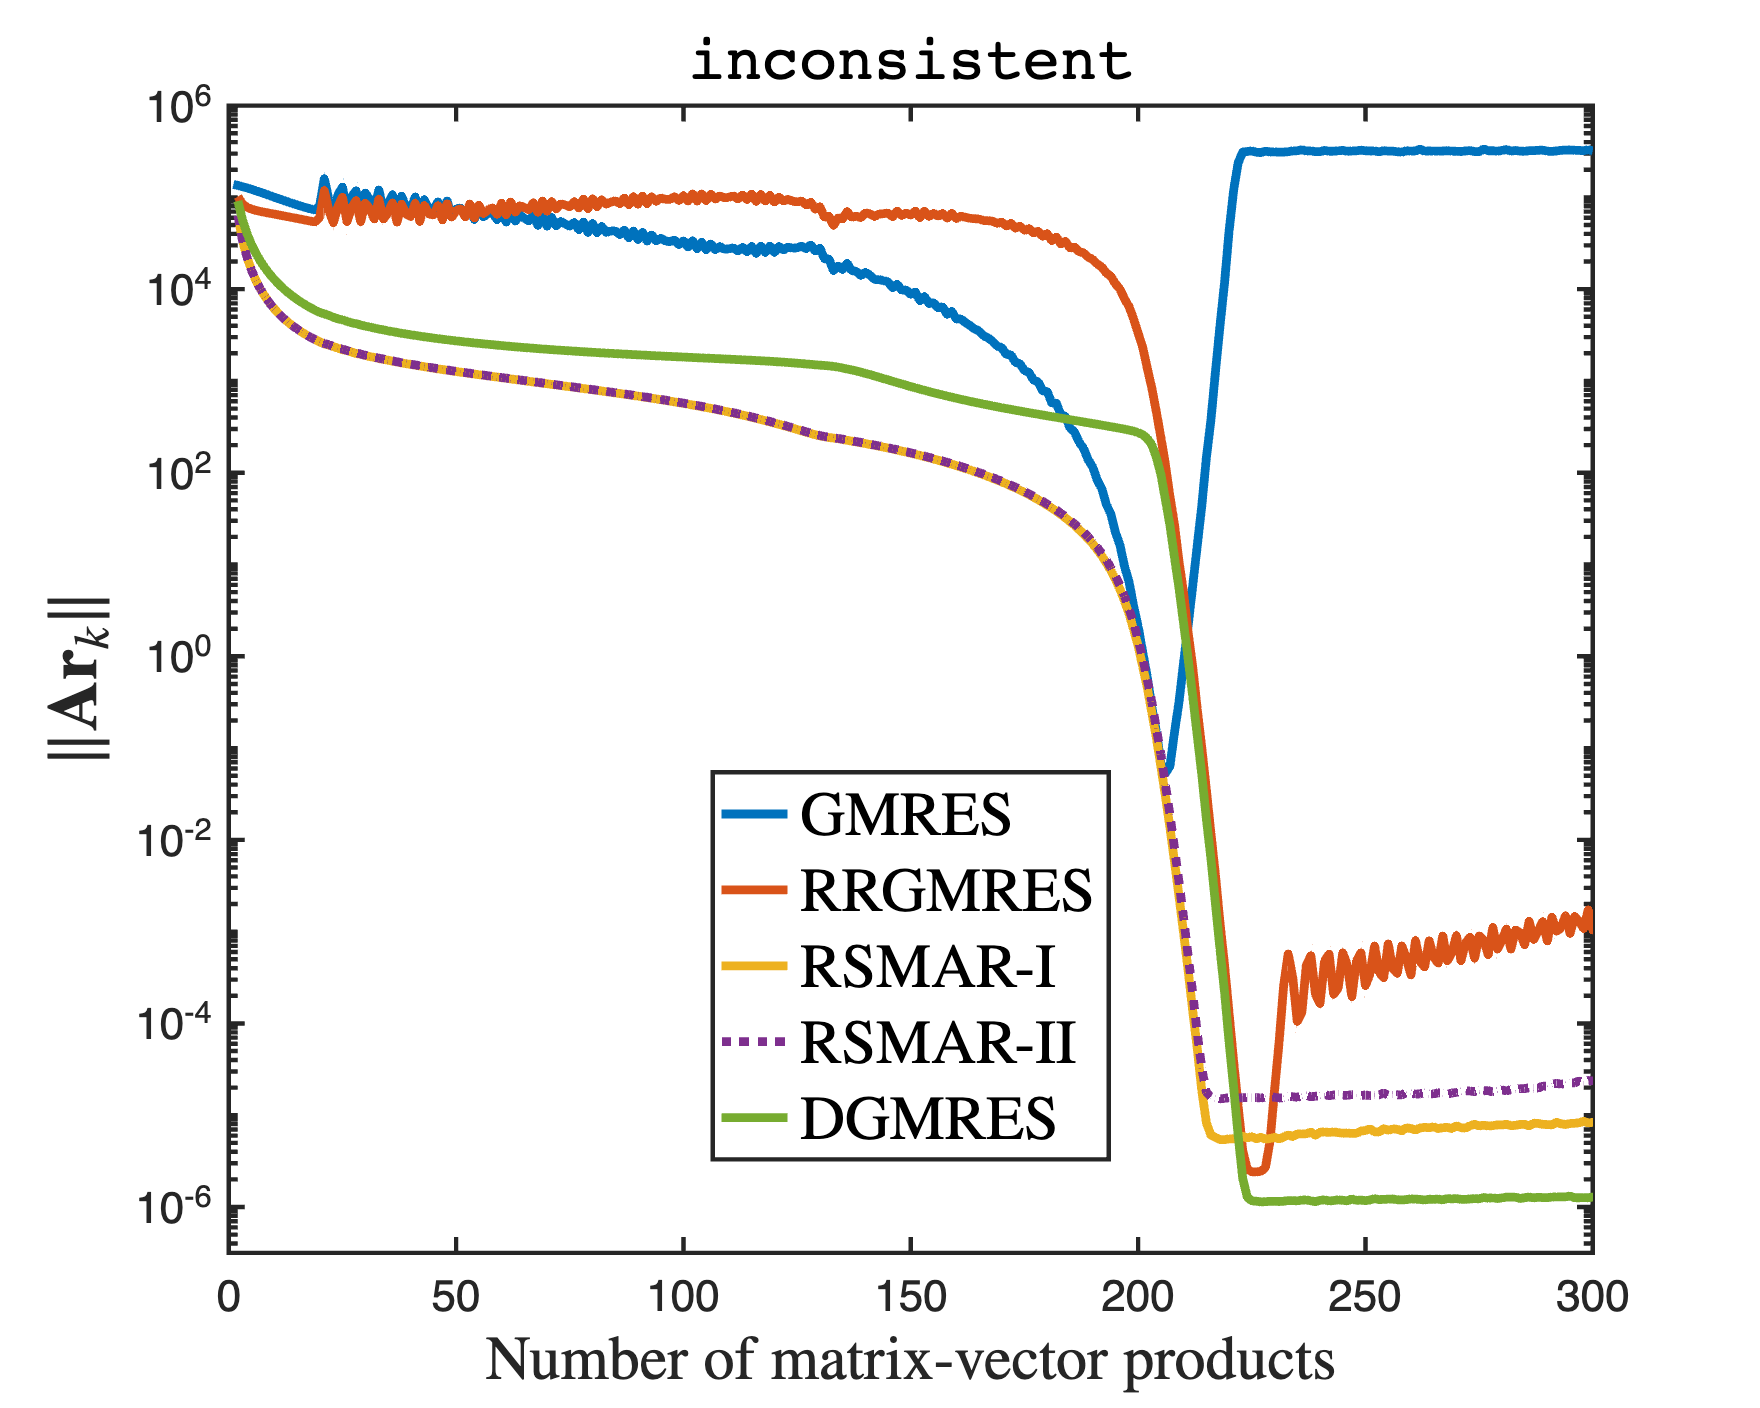

% range symmetric singular inconsistent system
% f = x+y
b = zeros(m^2, 1);
for i = 0:m-1
    for j = 0:m-1
        b(i*m + (j+1)) = (i + j) * h;
    end
end

tol = 1e-6; maxit = 300;
[~, ~, ~, gmres_Aresvec] = gmres(A, b, tol, maxit, criteria=2);
[~, ~, ~, rrgmres_Aresvec] = rrgmres(A, b, tol, maxit, version=2, criteria=2);
[~, ~, ~, rsmar1_Aresvec] = rsmar(A, b, tol, maxit, version=1, criteria=2);
[~, ~, ~, rsmar2_Aresvec] = rsmar(A, b, tol, maxit, version=2, criteria=2);
[~, ~, ~, dgmres_Aresvec] = dgmres(A, b, tol, maxit, criteria=2);

set(0, 'defaultaxeslinewidth',  2);
set(0, 'defaultaxesfontsize',   20);
figure('Position',[180 120 800 640]); 
semilogy(1:length(gmres_Aresvec), gmres_Aresvec, LineWidth=4);
hold on;
semilogy(2:length(rrgmres_Aresvec)+1, rrgmres_Aresvec, LineWidth=4);
semilogy(2:length(rsmar1_Aresvec)+1, rsmar1_Aresvec, LineWidth=4);
semilogy(2:length(rsmar2_Aresvec)+1, rsmar2_Aresvec, LineWidth=4, LineStyle=':');
semilogy(2:length(dgmres_Aresvec)+1, dgmres_Aresvec, LineWidth=4);
hold off;

xlim([0, maxit]), ylim([tol*10^(-0.5) 10^6])
title('{\tt inconsistent}', Interpreter='latex',FontSize=28);
xlabel('Number of matrix-vector products', Interpreter='latex', FontSize=28);
ylabel('$\|\mathbf{Ar}_k\|$', Interpreter='latex', FontSize=32);
legend({'GMRES', 'RRGMRES', 'RSMAR-I', 'RSMAR-II', 'DGMRES'}, Interpreter='latex', FontSize=28, Location='best');
print('bvp_incon','-depsc')

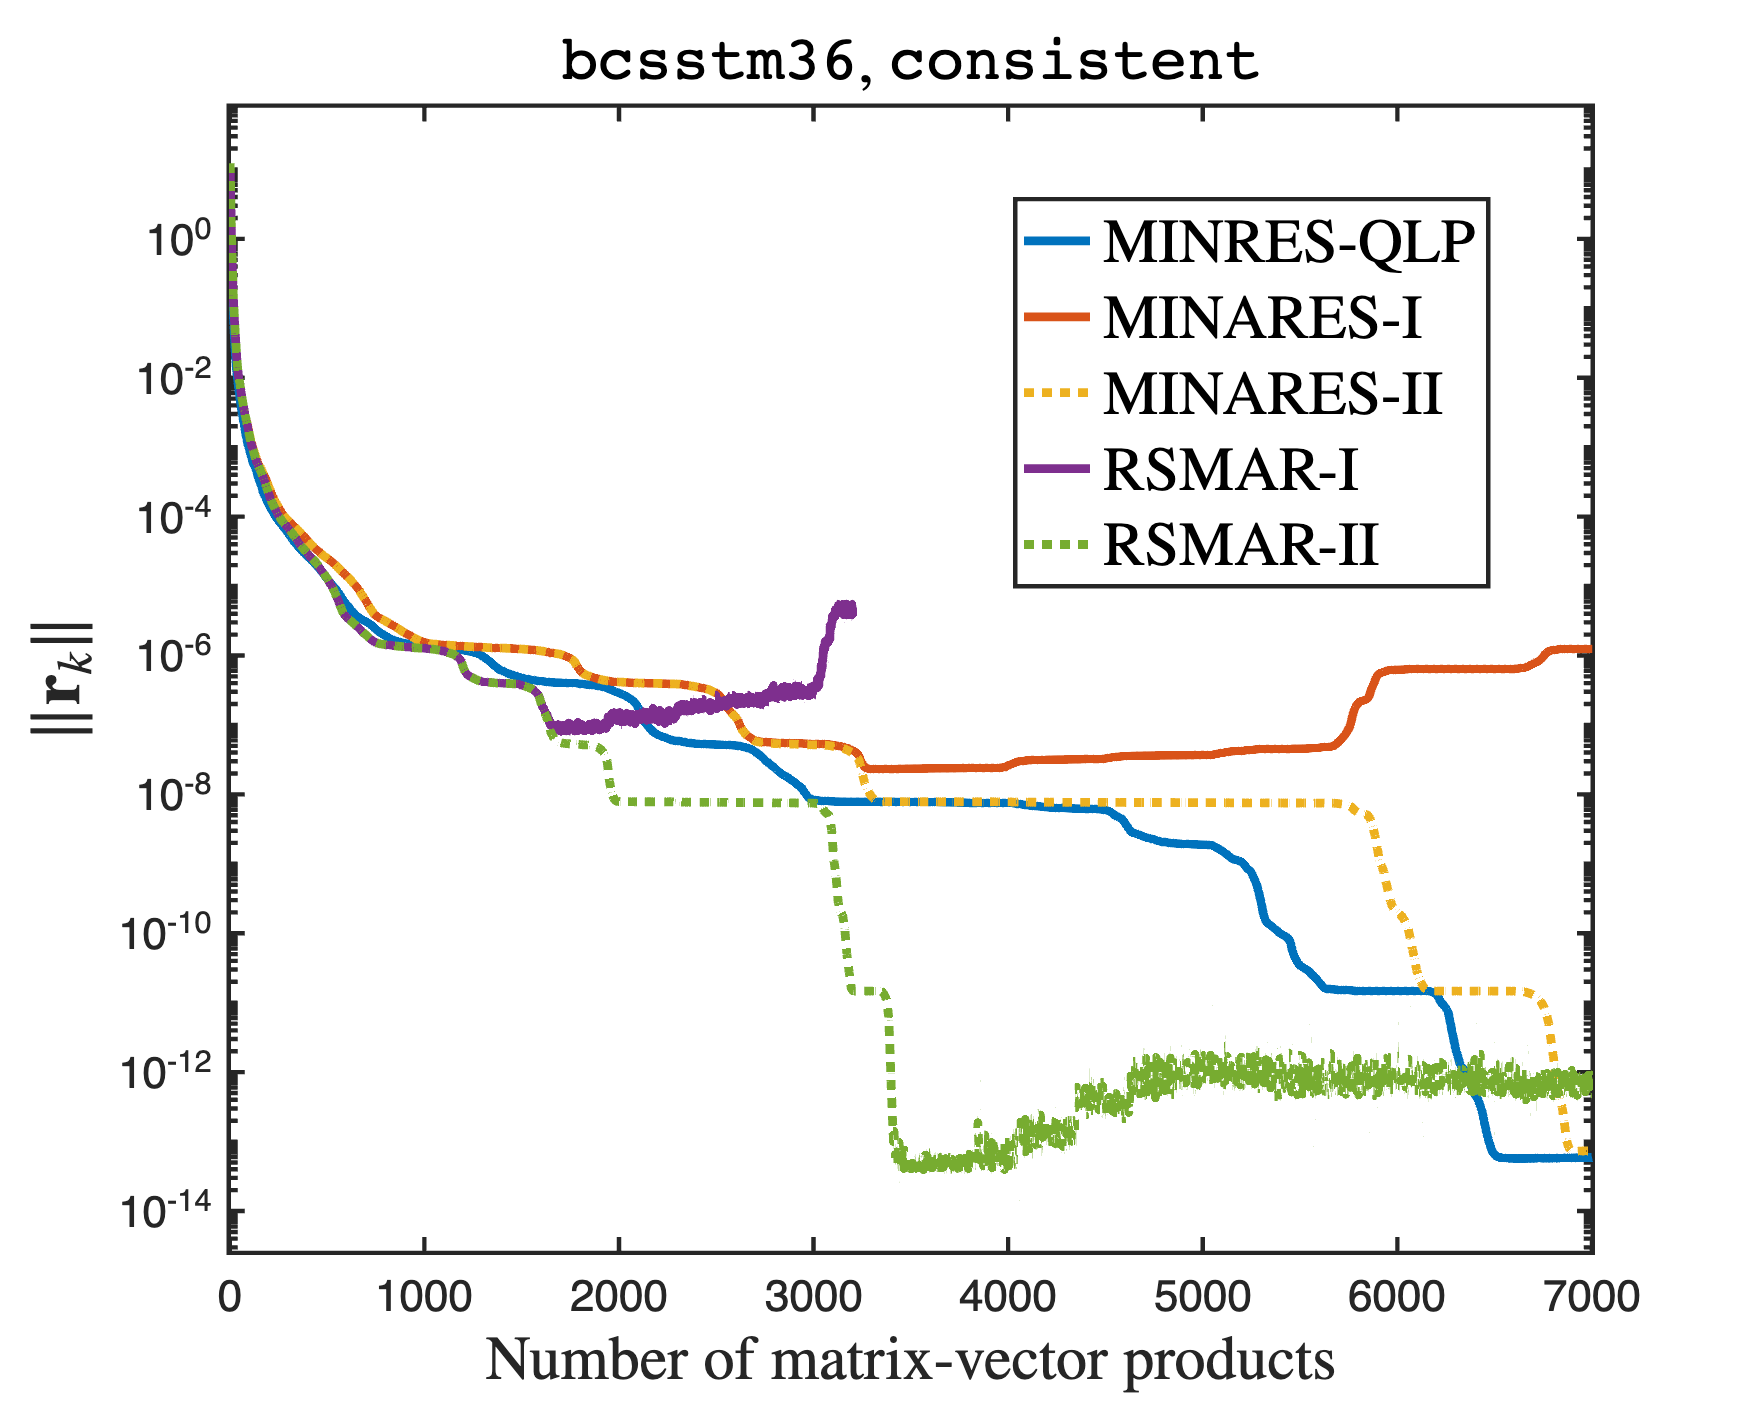

% singular symmetric consistent system
load("bcsstm36.mat");
A = Problem.A;
[~, n] = size(A);
A = A/max(max(abs(A)));

b = A * ones(n, 1);
tol = 1e-14; maxit = 7000; maxit2 = 3200;
[~, ~, minresqlp_resvec, ~] = minresqlp(A, b, tol, maxit, criteria=1);
[~, ~, minAres1_resvec, ~] = minares(A, b, tol, maxit, version=1, criteria=1);
[~, ~, minAres2_resvec, ~] = minares(A, b, tol, maxit, version=2, criteria=1);
[~, ~, rsmar1_resvec, ~] = rsmar(A, b, tol, maxit2, version=1, criteria=1);
[~, ~, rsmar2_resvec, ~] = rsmar(A, b, tol, maxit, version=2, criteria=1);

set(0, 'defaultaxeslinewidth',  2);
set(0, 'defaultaxesfontsize',   20);
figure('Position',[180 120 800 640]);
semilogy(1:length(minresqlp_resvec), minresqlp_resvec, LineWidth=4);
hold on;
semilogy(2:length(minAres1_resvec)+1, minAres1_resvec, LineWidth=4);
semilogy(2:length(minAres2_resvec)+1, minAres2_resvec, LineWidth=4, LineStyle=':');
semilogy(2:length(rsmar1_resvec)+1, rsmar1_resvec, LineWidth=4);
semilogy(2:length(rsmar2_resvec)+1, rsmar2_resvec, LineWidth=4, LineStyle=":");
hold off;

xlim([0, maxit]), ylim([tol*10^(-0.5) 10^2])
title('{\tt bcsstm36}, {\tt   consistent}', Interpreter='latex',FontSize=28);
xlabel('Number of matrix-vector products', Interpreter='latex', FontSize=28);
ylabel('$\|\mathbf{r}_k\|$', Interpreter='latex', FontSize=32);
legend({'MINRES-QLP', 'MINARES-I', 'MINARES-II', 'RSMAR-I', 'RSMAR-II'}, Interpreter='latex', FontSize=28, Location='best');
print('bcsstm36_con','-depsc')

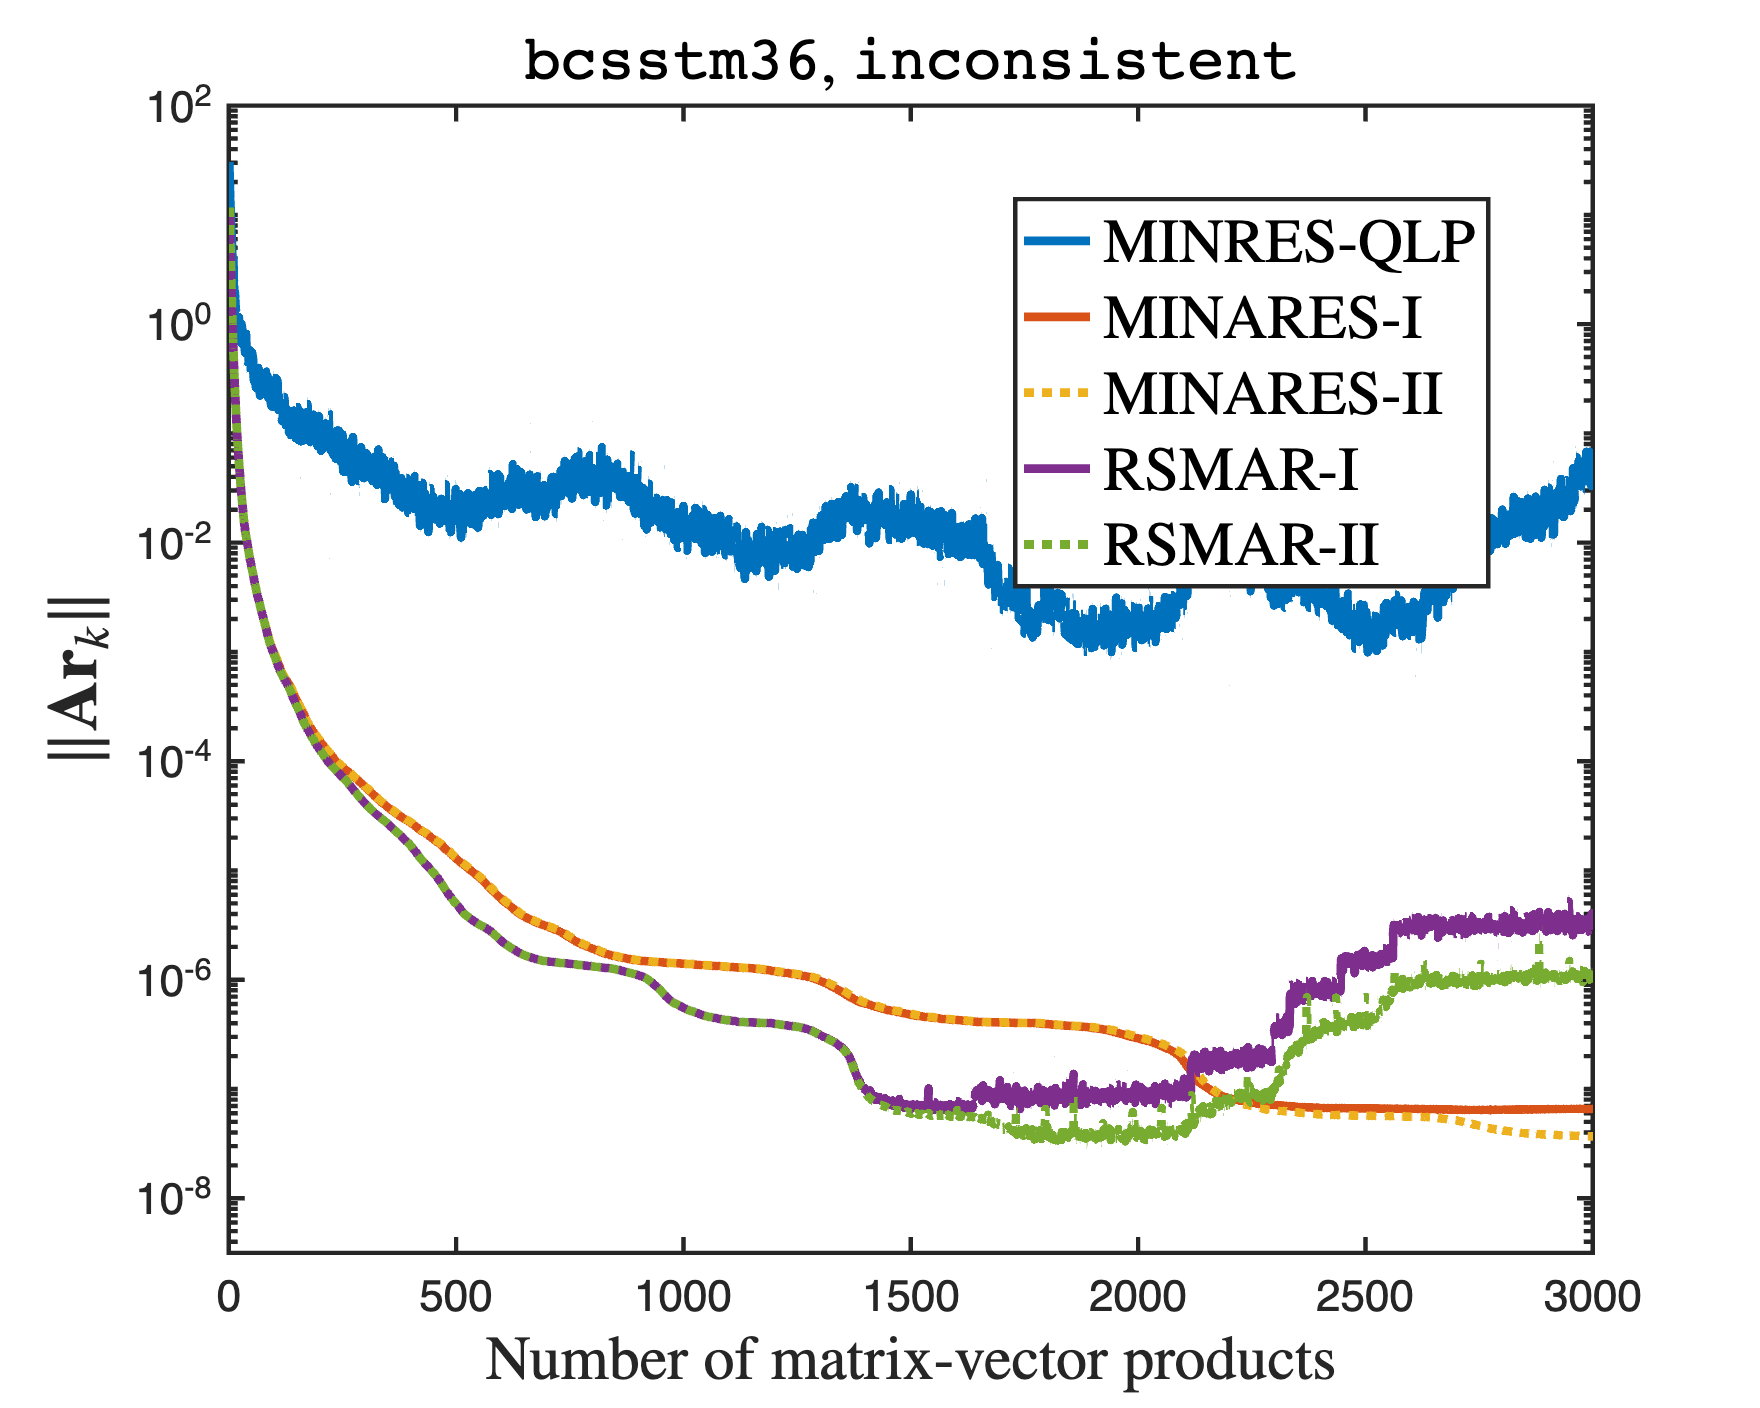

% singular symmetric inconsistent system

b = ones(n, 1);
tol = 1e-8; maxit = 3000; 
[~, ~, ~, minresqlp_Aresvec] = minresqlp(A, b, tol, maxit, criteria=2);
[~, ~, ~, minAres1_Aresvec] = minares(A, b, tol, maxit, version=1, criteria=2);
[~, ~, ~, minAres2_Aresvec] = minares(A, b, tol, maxit, version=2, criteria=2);
[~, ~, ~, rsmar1_Aresvec] = rsmar(A, b, tol, maxit, version=1, criteria=2);
[~, ~, ~, rsmar2_Aresvec] = rsmar(A, b, tol, maxit, version=2, criteria=2);

set(0, 'defaultaxeslinewidth',  2);
set(0, 'defaultaxesfontsize',   20);
figure('Position',[180 120 800 640]);
semilogy(1:length(minresqlp_Aresvec), minresqlp_Aresvec, LineWidth=4);
hold on;
semilogy(2:length(minAres1_Aresvec)+1, minAres1_Aresvec, LineWidth=4);
semilogy(2:length(minAres2_Aresvec)+1, minAres2_Aresvec, LineWidth=4, LineStyle=':');
semilogy(2:length(rsmar1_Aresvec)+1, rsmar1_Aresvec, LineWidth=4);
semilogy(2:length(rsmar2_Aresvec)+1, rsmar2_Aresvec, LineWidth=4, LineStyle=':');
hold off;

xlim([0, maxit]), ylim([tol*10^(-0.5) 10^2])
title('{\tt bcsstm36}, {\tt   inconsistent}', Interpreter='latex',FontSize=28);
xlabel('Number of matrix-vector products', Interpreter='latex', FontSize=28);
ylabel('$\|\mathbf{Ar}_k\|$', Interpreter='latex', FontSize=32);
legend({'MINRES-QLP', 'MINARES-I', 'MINARES-II', 'RSMAR-I', 'RSMAR-II'}, Interpreter='latex', FontSize=28, Location='best');
print('bcsstm36_incon','-depsc')

% singular symmetric consistent system
load("zenios.mat");
A = Problem.A;
[~, n] = size(A);
A = A/max(max(abs(A)));

b = A * ones(n, 1);
tol = 1e-15; maxit = 8000; maxit2 = 275;
[~, ~, minresqlp_resvec, ~] = minresqlp(A, b, tol, maxit, criteria=1);
[~, ~, minAres1_resvec, ~] = minares(A, b, tol, maxit, version=1, criteria=1);
[~, ~, minAres2_resvec, ~] = minares(A, b, tol, maxit, version=2, criteria=1);
[~, ~, rsmar1_resvec, ~] = rsmar(A, b, tol, maxit2, version=1, criteria=1);

[~, ~, rsmar2_resvec, ~] = rsmar(A, b, tol, maxit2, version=2, criteria=1);

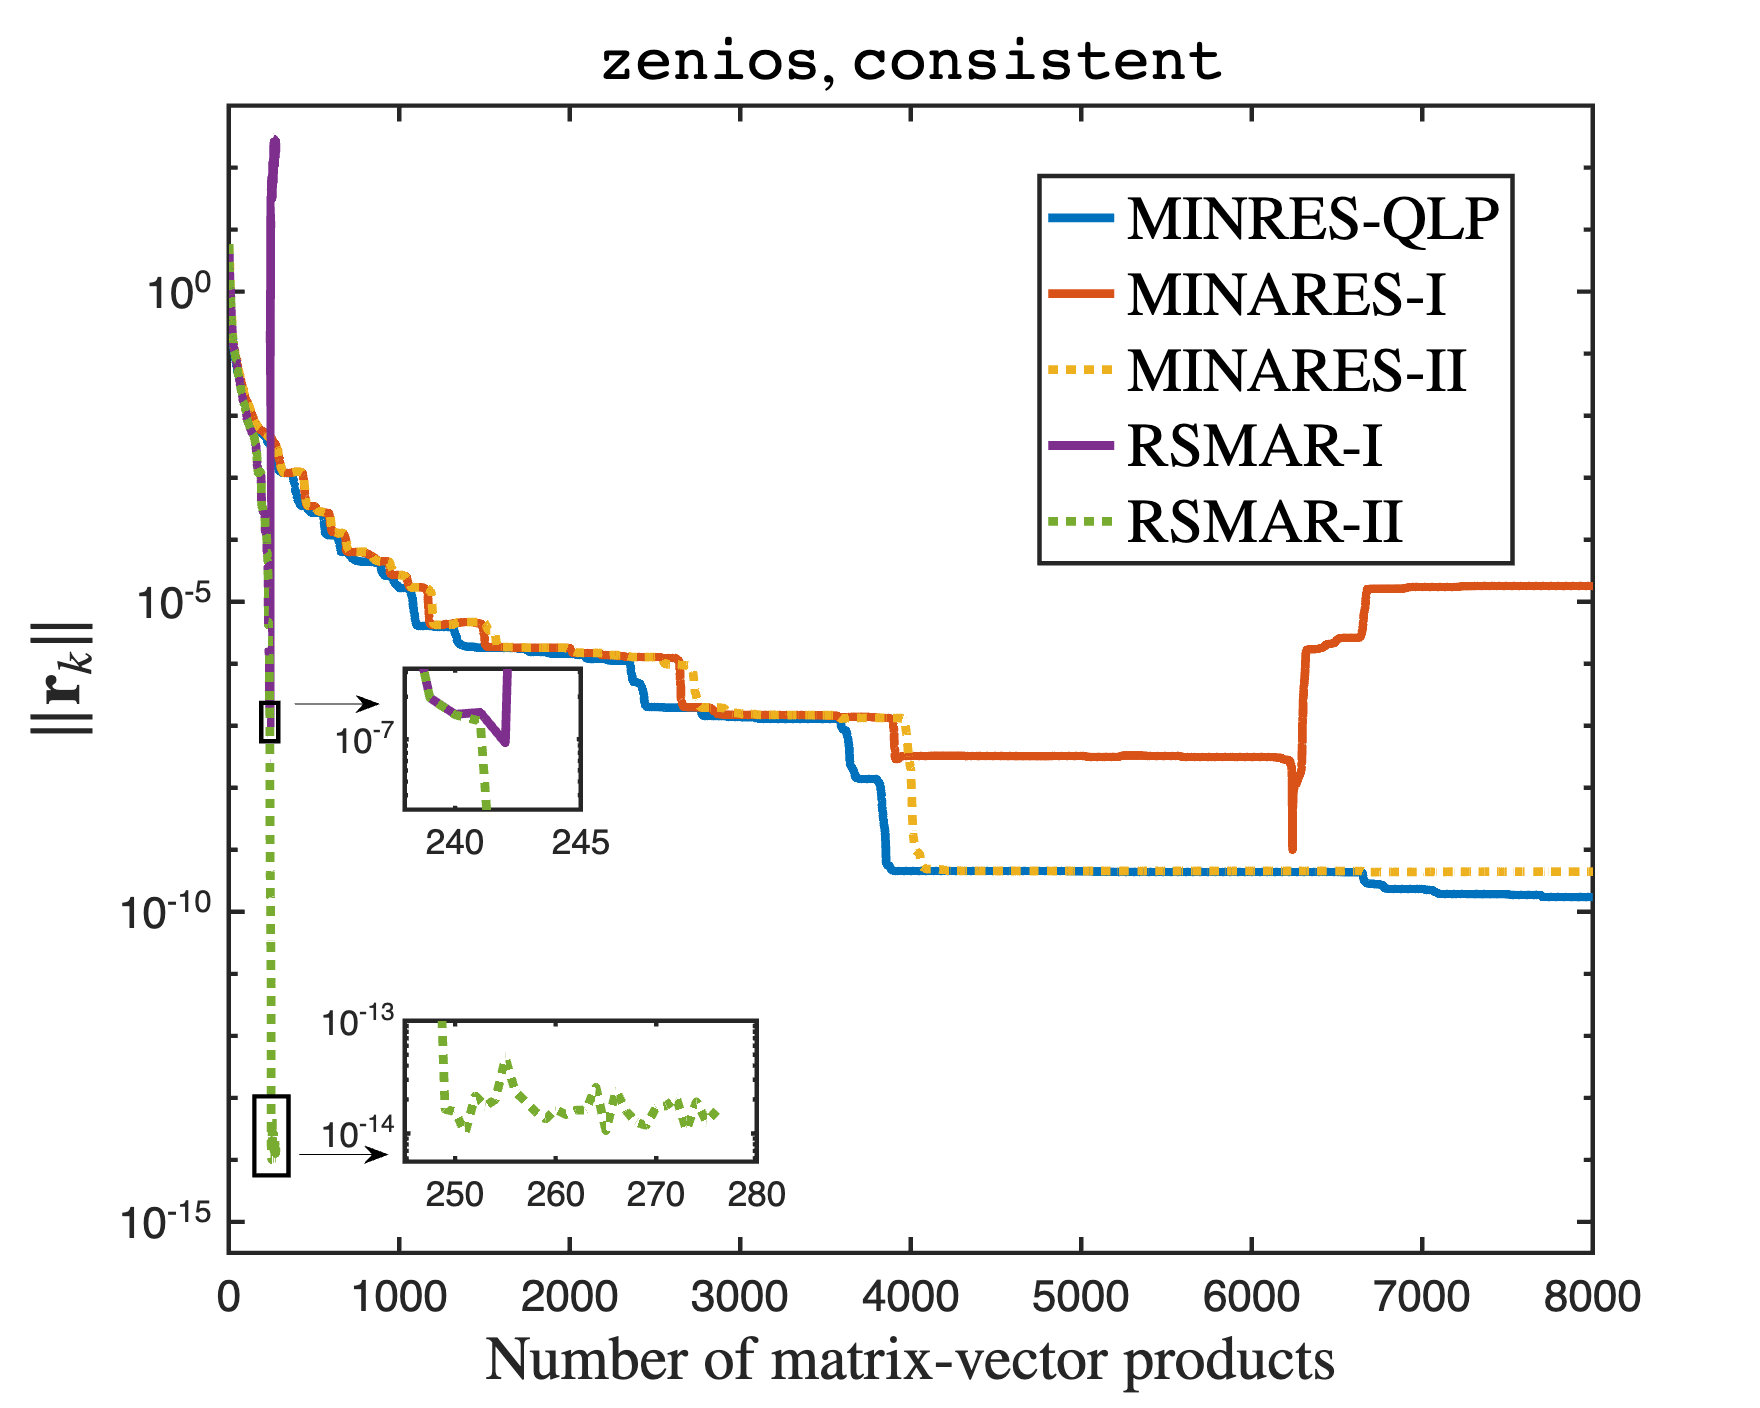


set(0, 'defaultaxeslinewidth',  2);
set(0, 'defaultaxesfontsize',   20);
figure('Position',[180 120 800 640]);
semilogy(1:length(minresqlp_resvec), minresqlp_resvec, LineWidth=4);
hold on;
semilogy(2:length(minAres1_resvec)+1, minAres1_resvec, LineWidth=4);
semilogy(2:length(minAres2_resvec)+1, minAres2_resvec, LineWidth=4, LineStyle=':');
semilogy(2:length(rsmar1_resvec)+1, rsmar1_resvec, LineWidth=4);
semilogy(2:length(rsmar2_resvec)+1, rsmar2_resvec, LineWidth=4, LineStyle=":");
hold off;

xlim([0, maxit]), ylim([tol*10^(-.5) 10^3])
title('{\tt zenios}, {\tt   consistent}', Interpreter='latex',FontSize=28);
xlabel('Number of matrix-vector products', Interpreter='latex', FontSize=28);
ylabel('$\|\mathbf{r}_k\|$', Interpreter='latex', FontSize=32);
legend({'MINRES-QLP', 'MINARES-I', 'MINARES-II', 'RSMAR-I', 'RSMAR-II'}, Interpreter='latex', FontSize=28);
legend("Position", [0.60,0.60,0.25,0.275])

rectangle('Position',[150 10^(-14.25) 200 10^(-13)], 'EdgeColor', 'k', 'LineWidth', 2)
rectangle('Position',[190 10^(-7.25) 100 10^(-6.75)], 'EdgeColor', 'k', 'LineWidth', 2)
annotation("arrow", [0.1675 0.215], [0.5 0.5])
annotation("arrow", [0.17 0.22], [0.18 0.18])

H1 = axes('Position',[0.23,0.425,0.1,0.1]);
semilogy(1:length(minresqlp_resvec), minresqlp_resvec, LineWidth=4);
hold on;
semilogy(2:length(minAres1_resvec)+1, minAres1_resvec, LineWidth=4);
semilogy(2:length(minAres2_resvec)+1, minAres2_resvec, LineWidth=4, LineStyle=':');
semilogy(2:length(rsmar1_resvec)+1, rsmar1_resvec, LineWidth=4);
semilogy(2:length(rsmar2_resvec)+1, rsmar2_resvec, LineWidth=4, LineStyle=":");
xlim([238 245]), ylim([10^(-7.5) 10^(-6.5)])
% set(H1, 'XTick',[240 245], 'YTick',[ ]);
box on;

H2 = axes('Position',[0.23,0.175,0.2,0.1]);
semilogy(1:length(minresqlp_resvec), minresqlp_resvec, LineWidth=4);
hold on;
semilogy(2:length(minAres1_resvec)+1, minAres1_resvec, LineWidth=4);
semilogy(2:length(minAres2_resvec)+1, minAres2_resvec, LineWidth=4, LineStyle=':');
semilogy(2:length(rsmar1_resvec)+1, rsmar1_resvec, LineWidth=4);
semilogy(2:length(rsmar2_resvec)+1, rsmar2_resvec, LineWidth=4, LineStyle=":");
xlim([245 280]), ylim([10^(-14.25) 10^(-13)])
% set(H2, 'XTick',[], 'YTick', []);
box on;

print('zenios_con','-depsc')


% singular symmetric inconsistent system
b = ones(n, 1);
tol = 1e-8; maxit = 8000; maxit2 = 250;
[~, ~, ~, minresqlp_Aresvec] = minresqlp(A, b, tol, maxit, criteria=2);
[~, ~, ~, minAres1_Aresvec] = minares(A, b, tol, maxit, version=1, criteria=2);
[~, ~, ~, minAres2_Aresvec] = minares(A, b, tol, maxit, version=2, criteria=2);
[~, ~, ~, rsmar1_Aresvec] = rsmar(A, b, tol, maxit2, version=1, criteria=2);

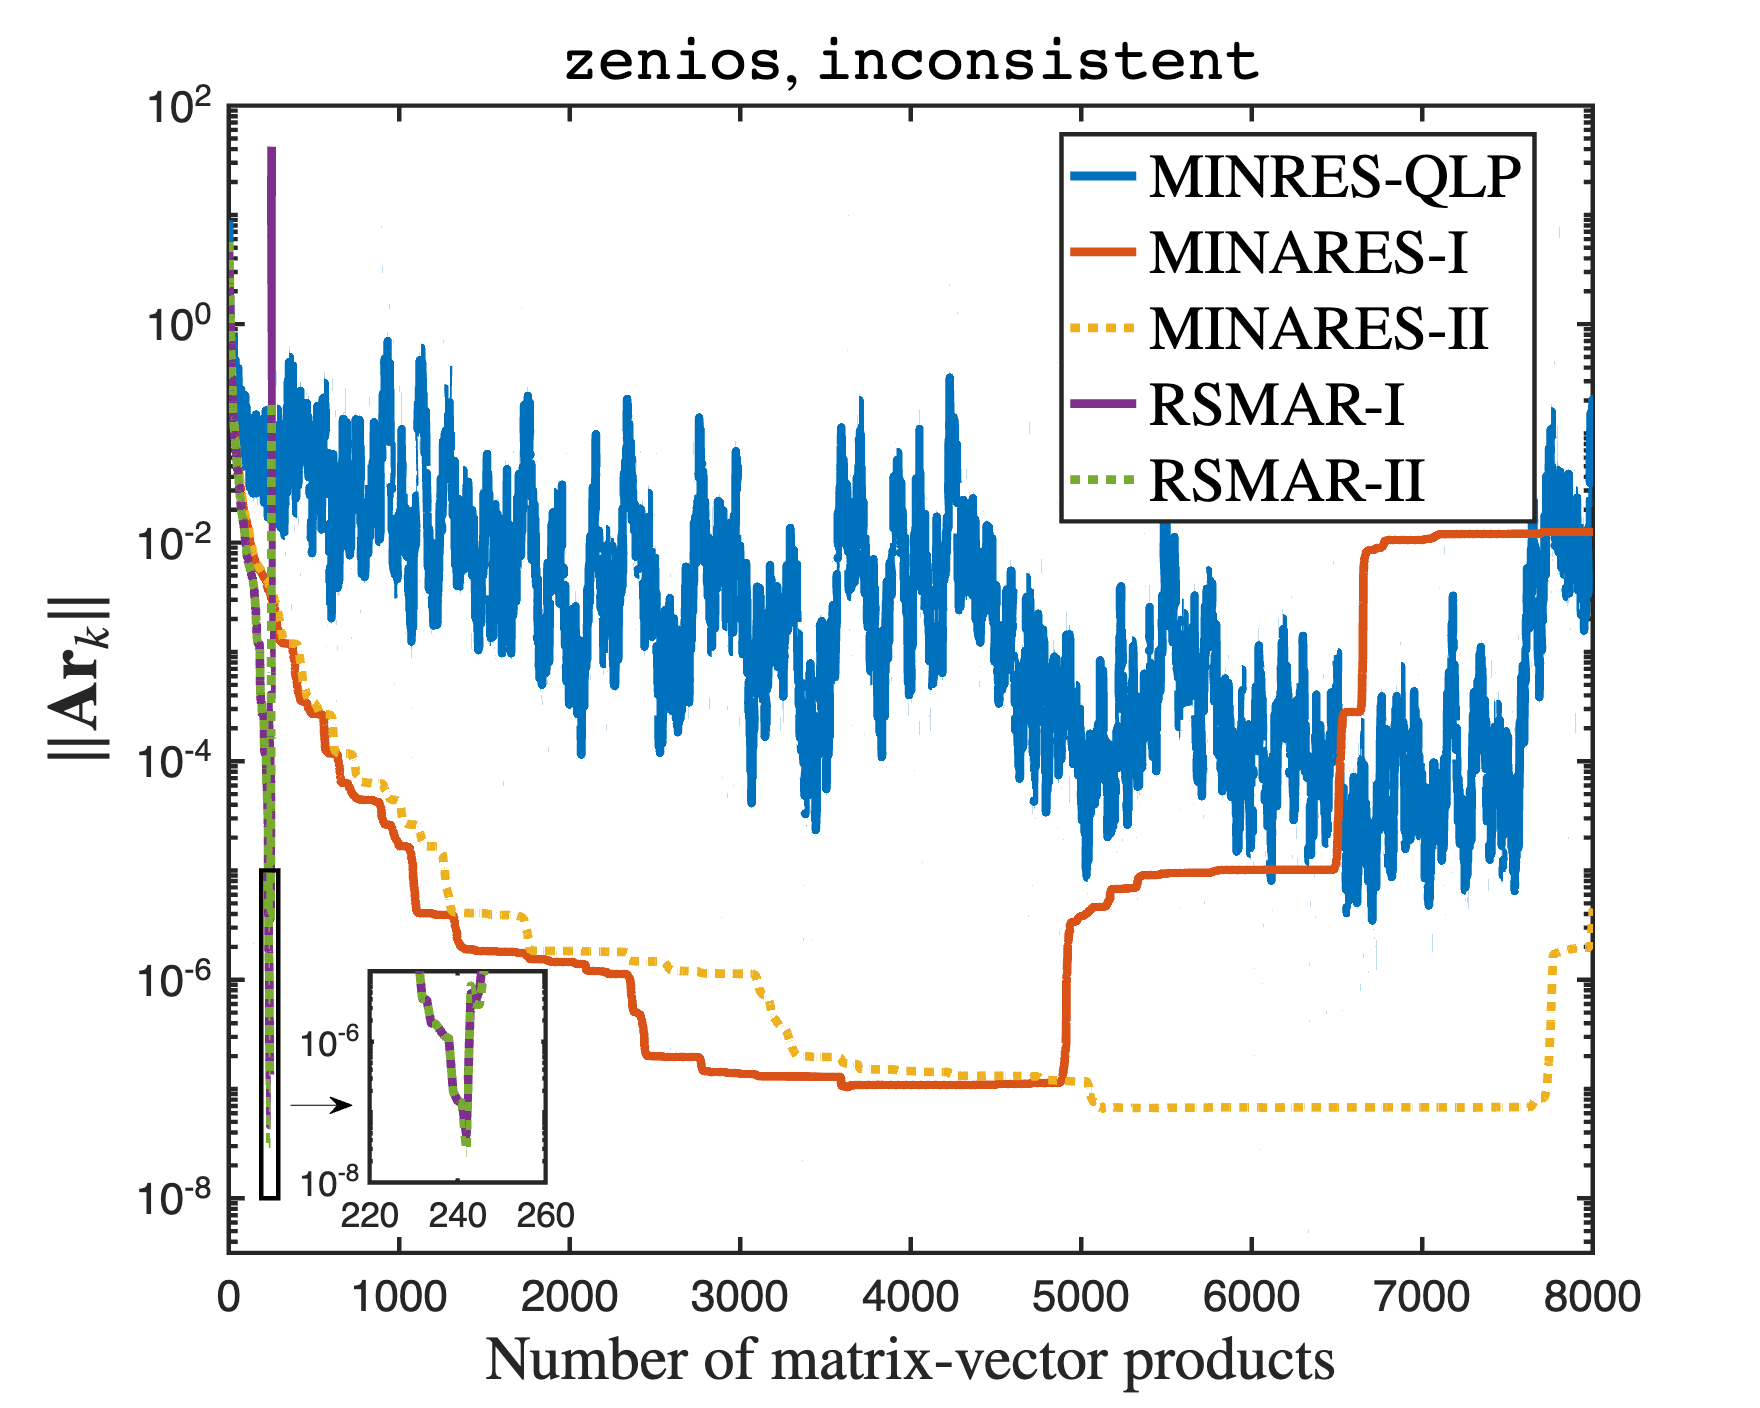

[~, ~, ~, rsmar2_Aresvec] = rsmar(A, b, tol, maxit2, version=2, criteria=2);

set(0, 'defaultaxeslinewidth',  2);
set(0, 'defaultaxesfontsize',   20);
figure('Position',[180 120 800 640]);
semilogy(1:length(minresqlp_Aresvec), minresqlp_Aresvec, LineWidth=4);
hold on;
semilogy(2:length(minAres1_Aresvec)+1, minAres1_Aresvec, LineWidth=4);
semilogy(2:length(minAres2_Aresvec)+1, minAres2_Aresvec, LineWidth=4, LineStyle=':');
semilogy(2:length(rsmar1_Aresvec)+1, rsmar1_Aresvec, LineWidth=4);
semilogy(2:length(rsmar2_Aresvec)+1, rsmar2_Aresvec, LineWidth=4, LineStyle=':');
hold off;

xlim([0, maxit]), ylim([tol*10^(-0.5) 10^2])
title('{\tt zenios}, {\tt   inconsistent}', Interpreter='latex',FontSize=28);
xlabel('Number of matrix-vector products', Interpreter='latex', FontSize=28);
ylabel('$\|\mathbf{Ar}_k\|$', Interpreter='latex', FontSize=32);
legend({'MINRES-QLP', 'MINARES-I', 'MINARES-II', 'RSMAR-I', 'RSMAR-II'}, Interpreter='latex', FontSize=28, Location='best');
% axes 1
legend("Position", [0.6,0.63,0.275,0.275])

rectangle('Position',[190 10^(-8) 100 10^(-5)], 'EdgeColor', 'k', 'LineWidth', 2)
annotation("arrow", [0.165 0.2], [0.215 0.215])

H = axes('Position',[0.21,0.16,0.1,0.15]);
semilogy(1:length(minresqlp_Aresvec), minresqlp_Aresvec, LineWidth=4);
hold on;
semilogy(2:length(minAres1_Aresvec)+1, minAres1_Aresvec, LineWidth=4);
semilogy(2:length(minAres2_Aresvec)+1, minAres2_Aresvec, LineWidth=4, LineStyle=':');
semilogy(2:length(rsmar1_Aresvec)+1, rsmar1_Aresvec, LineWidth=4);
semilogy(2:length(rsmar2_Aresvec)+1, rsmar2_Aresvec, LineWidth=4, LineStyle=':');
xlim([220 260]), ylim([10^(-8) 10^(-5)])
% set(H, 'XTick',[], 'YTick', []);
box on;

print('zenios_incon','-depsc')

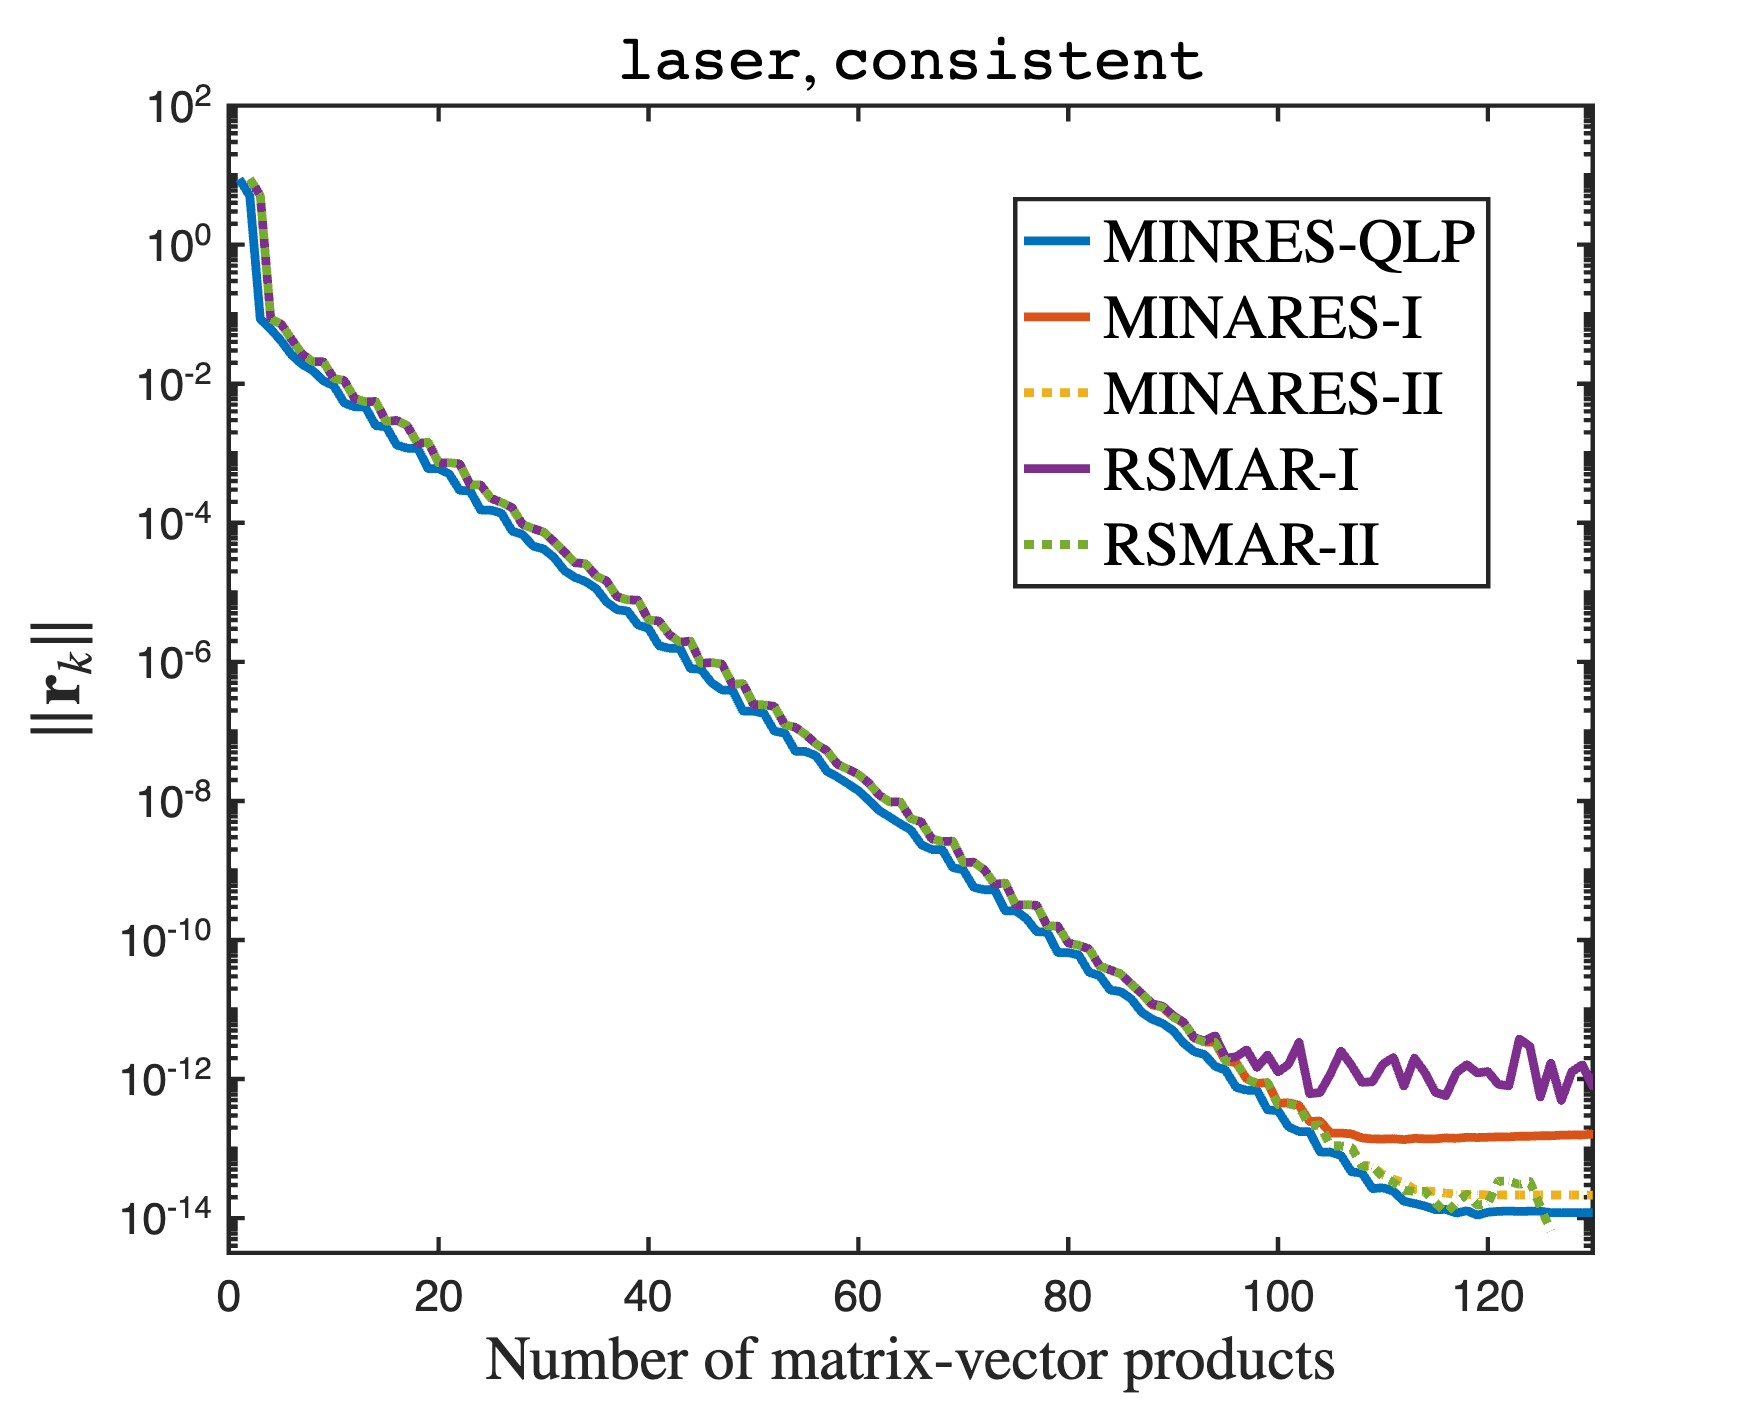

% singular symmetric consistent system
load("laser.mat");
A = Problem.A;
[~, n] = size(A);
A = A/max(max(abs(A)));

b = A * ones(n, 1);
tol = 1e-14; maxit = 130;
[~, ~, minresqlp_resvec, ~] = minresqlp(A, b, tol, maxit, criteria=1);
[~, ~, minAres1_resvec, ~] = minares(A, b, tol, maxit, version=1, criteria=1);
[~, ~, minAres2_resvec, ~] = minares(A, b, tol, maxit, version=2, criteria=1);
[~, ~, rsmar1_resvec, ~] = rsmar(A, b, tol, maxit, version=1, criteria=1);
[~, ~, rsmar2_resvec, ~] = rsmar(A, b, tol, maxit, version=2, criteria=1);

set(0, 'defaultaxeslinewidth',  2);
set(0, 'defaultaxesfontsize',   20);
figure('Position',[180 120 800 640]);
semilogy(1:length(minresqlp_resvec), minresqlp_resvec, LineWidth=4);
hold on;
semilogy(2:length(minAres1_resvec)+1, minAres1_resvec, LineWidth=4);
semilogy(2:length(minAres2_resvec)+1, minAres2_resvec, LineWidth=4, LineStyle=':');
semilogy(2:length(rsmar1_resvec)+1, rsmar1_resvec, LineWidth=4);
semilogy(2:length(rsmar2_resvec)+1, rsmar2_resvec, LineWidth=4, LineStyle=":");
hold off;

xlim([0, maxit]), ylim([tol*10^(-0.5) 10^2])
title('{\tt laser}, {\tt   consistent}', Interpreter='latex',FontSize=28);
xlabel('Number of matrix-vector products', Interpreter='latex', FontSize=28);
ylabel('$\|\mathbf{r}_k\|$', Interpreter='latex', FontSize=32);
legend({'MINRES-QLP', 'MINARES-I', 'MINARES-II', 'RSMAR-I', 'RSMAR-II'}, Interpreter='latex', FontSize=28, Location='best');
print('laser_con','-depsc')

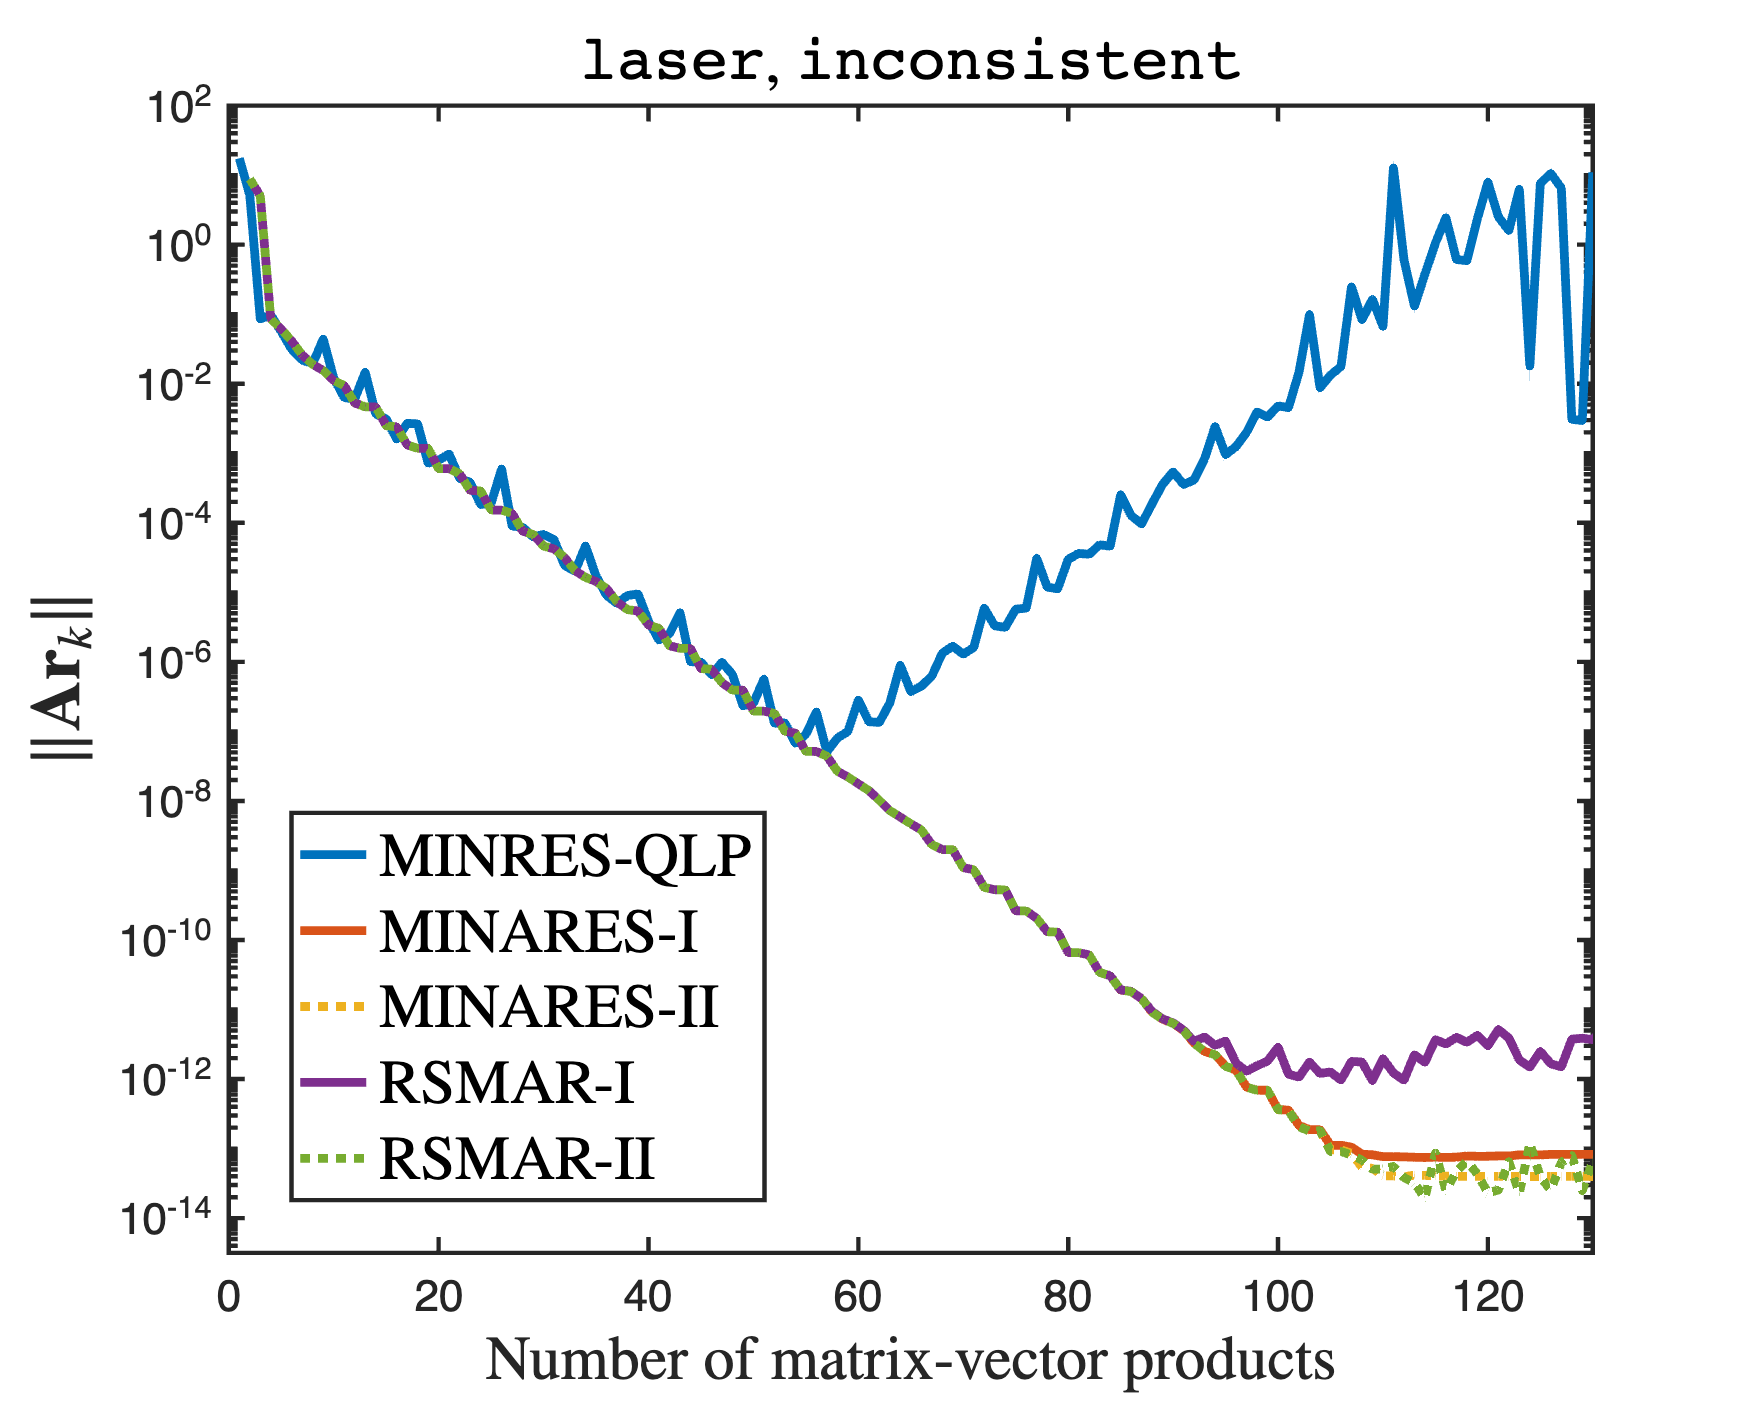

% singular symmetric inconsistent system
b = ones(n, 1);
tol = 1e-14; maxit = 130;
[~, ~, ~, minresqlp_Aresvec] = minresqlp(A, b, tol, maxit, criteria=2);
[~, ~, ~, minAres1_Aresvec] = minares(A, b, tol, maxit, version=1, criteria=2);
[~, ~, ~, minAres2_Aresvec] = minares(A, b, tol, maxit, version=2, criteria=2);
[~, ~, ~, rsmar1_Aresvec] = rsmar(A, b, tol, maxit, version=1, criteria=2);
[~, ~, ~, rsmar2_Aresvec] = rsmar(A, b, tol, maxit, version=2, criteria=2);

set(0, 'defaultaxeslinewidth',  2);
set(0, 'defaultaxesfontsize',   20);
figure('Position',[180 120 800 640]);
semilogy(1:length(minresqlp_Aresvec), minresqlp_Aresvec, LineWidth=4);
hold on;
semilogy(2:length(minAres1_Aresvec)+1, minAres1_Aresvec, LineWidth=4);
semilogy(2:length(minAres2_Aresvec)+1, minAres2_Aresvec, LineWidth=4, LineStyle=':');
semilogy(2:length(rsmar1_Aresvec)+1, rsmar1_Aresvec, LineWidth=4);
semilogy(2:length(rsmar2_Aresvec)+1, rsmar2_Aresvec, LineWidth=4, LineStyle=':');
hold off;

xlim([0, maxit]), ylim([tol*10^(-0.5) 10^2])
title('{\tt laser}, {\tt   inconsistent}', Interpreter='latex',FontSize=28);
xlabel('Number of matrix-vector products', Interpreter='latex', FontSize=28);
ylabel('$\|\mathbf{Ar}_k\|$', Interpreter='latex', FontSize=32);
legend({'MINRES-QLP', 'MINARES-I', 'MINARES-II', 'RSMAR-I', 'RSMAR-II'}, Interpreter='latex', FontSize=28);
legend("Position", [0.175,0.16,0.25,0.25])
print('laser_incon','-depsc')